Q1 a

%parameters
Par.alpha = 0.36;
Par.beta = 0.98;
Par.delta = 0.03;
Par.gamma = 2;

%input parameters
Par.N = 5;
Par.mu = 0;
Par.rho = 0.7;
Par.sigma = 0.1;
Par.m = 3;

%Tauchen
[Z, Zprob] = tauchen(N,mu,rho, sigma,m);

M = Zprob - eye(N);
M(:, N) = ones(N,1);

c = zeros(N,1);
c(N) = 1;

pi = linsolve(M', c);

Z

Z =    -0.4201
   -0.2100
         0
    0.2100
    0.4201


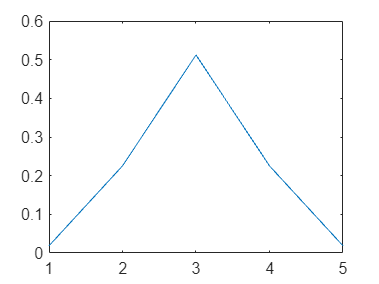


plot(pi)

b

%in this case, we have steady state k:
k_s = (delta/alpha)^(1-alpha);
k_grid = linspace(0.01*k_s, 4*k_s, 1000);


c

clc;
k_grid = linspace(0, 1, 10);
w = ones(10, 1)

w =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


%for i = [1:5]
    [policy, w] = simple_max_1(k_grid, 1, w, Par)

policy =      2
     7
     9
    10
     1
     1
     1
     1
     1
     1


w =     9.0000
    9.4788
   10.9362
  300.8723
   -0.8489
   -0.7417
   -0.6619
   -0.5995
   -0.5492
   -0.5076


%end

[w2, k2] = simple_max_1([1:10], 1,zeros(10, 1),Par);



function u = U(x, Par)
    if Par.gamma==1
        u=log(x);
    else
        u=(x.^(1-Par.gamma))/(1-Par.gamma);
    end
end

function kt = f(k,z, Par)
    kt = z*((k.^Par.alpha)+(1-Par.delta)*k);
end



function [kp, wp] = simple_max_1(k_g, z, w1, Par)
    Nk = length(k_g);
    kp = zeros(Nk, 1);
    wp = zeros(Nk, 1);
    for i = [1:Nk]
        w2 = 0;
        kj = 0;
        for j = [1:Nk]
            if U(f(kj, z, ))
        end
        [w2, kj] = max(U(f(k_g(i),z, Par)-k_g(j), Par)+beta*w1(j));
        wp(i) = w2;
        kp(i) = kj;
    end
end


% function [kp, wp] = simple_max_1(k_grid, )
% 
% end